# Lecture 6 Control Flows II: Conditional Statements

## Logical Datatype and Operations

logical is one basic datatype in Matlab, in addition to numeric

class(true)
class(false)
true + true  % for numerical operations, true is viewed as one and false is zero
sum([true true false]) %total number of true elements
logical([0 1 2]) % convert numeric to logical: 0 is false and non zero is true

Basic operations/functions for logical variables:

true & true  % and 
~true  % not
true | false % or
0 | 1 % won't feel surprise now
any([true false false])
all([true false])

Recall the relational operators for numeric arrays can also create logical arrays. 

v = [1 2 3 1];
sum(v==1) % equal to, note the doulbe = here
sum(v~=1) % not equal to
sum(v(v~=1)) %compare with the example above
v(v>=2)
any(v>2)
all(v<4)

## The If Statement

The simplest case:

x = rand % random number from 0 to 1
if x>0.5
    disp("x is greater than 0.5")
end

if-else statement

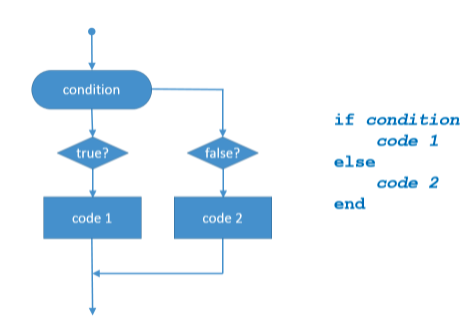

x = rand;
if x>0.5
    y = 1
else
    y = 0
end

For multiple conditions: using `elseif`

x = randn %normal
if x > 0   %condition 1
    disp('positive')
elseif x<0 %condition 2
    disp('negative')
else  %all the remaining case
    disp('zero')
end

Logical operations for various statements: it's recommended to use double signs ([short-circuit logical operations](https://www.mathworks.com/help/matlab/ref/logicaloperatorsshortcircuit.html)) &&(and) ||(or) for the efficiency of code.

x = 0;
if x > 0 || x<0  % or, note the double || here, you can also use the single |, but double is recommended
    disp('non-zero')
else  %all the remaining case
    disp('zero')
end

x = 4;
if x ~= 0  % not equal to
    disp('non-zero')
else  %all the remaining case
    disp('zero')
end

**Exercise 1: **Define the function `isodd(n) `whose input is the positive integer n, and return true if n is odd and false if n is even. *Hint: use the mod function to find the remainder of division.*

**Exercise 2: **Define the function `mydivisors(n) `whose input is the positive integer n, and return the row vector containing all the positive divisors of n. *Hint: combining the loop and if statement.*

## The Switch Statement

A convenient replacement for multiple elseif conditions.

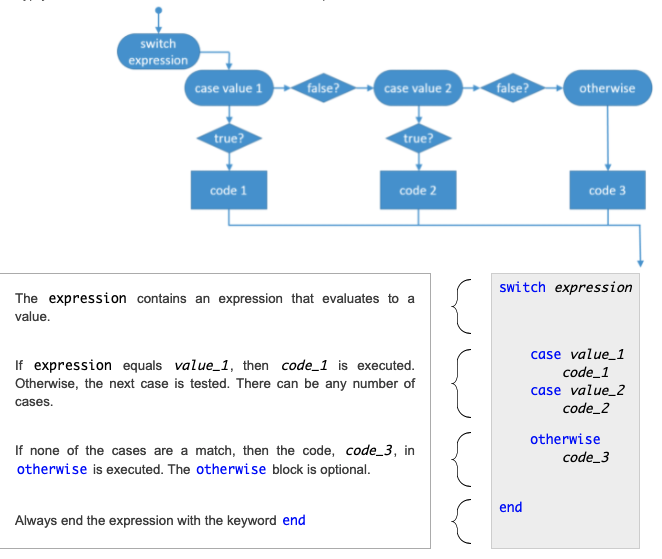

n = 1;
switch n
    case -1
        disp('negative one')
    case 0
        disp('zero')
    case 1
        disp('positive one')
    otherwise  % all the remaining cases
        disp('other value')
end

**Exercise: **Define the function `myintegral(f,a,b,n,formula), `where formula is the input character 'left'  'right' 'midpoint' 'trapezoidal', indicuating the numerical integral formula to use.

myintegral(@sin,0,pi/2,100,'trapezoidal')

**Remark**: here the convenient way is to use switch statements. To use if statement, you should use `strcmp` function to compare the equivalence of characters (not ===).